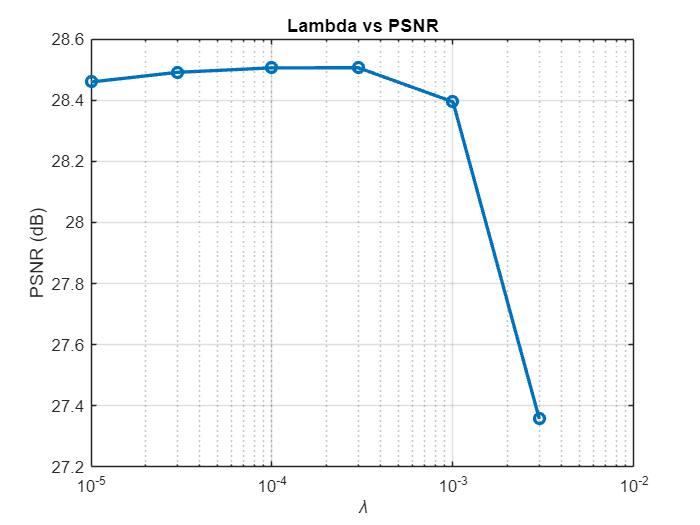

clc; clear; close all;
tic

%% ================= IMAGE =================
img = im2double(imread('cameraman.tif'));
[n1,n2] = size(img);

%% ================= FIXED PARAMETERS =================
blur_size = 5;
noise = 0.003;

innerIter = 20;
maxIter = 150;

lambda_base = 1e-4;
rho_base = 3;
v_base = 2.5;

%% ================= BLUR =================
h = fspecial('gaussian',blur_size,2);
h = h/sum(h(:));

A = @(x) imfilter(x,h,'circular');
AT = @(x) imfilter(x,h,'circular');

%% ================= BLUR + NOISE =================
b_img = A(img);
b_img = b_img + noise*randn(size(img));

%% ===================================================
%% LAMBDA EXPERIMENT
%% ===================================================

lambda_vals = [1e-5 3e-5 1e-4 3e-4 1e-3 3e-3];
psnr_lambda = zeros(length(lambda_vals),1);

for i = 1:length(lambda_vals)
psnr_lambda(i) = run_ilstat(lambda_vals(i),rho_base,v_base,b_img,A,AT,img,innerIter,maxIter);
end

[~,idx] = max(psnr_lambda);
best_lambda = lambda_vals(idx);

figure
semilogx(lambda_vals,psnr_lambda,'-o','LineWidth',2)
grid on
xlabel('\lambda')
ylabel('PSNR (dB)')
title('Lambda vs PSNR')

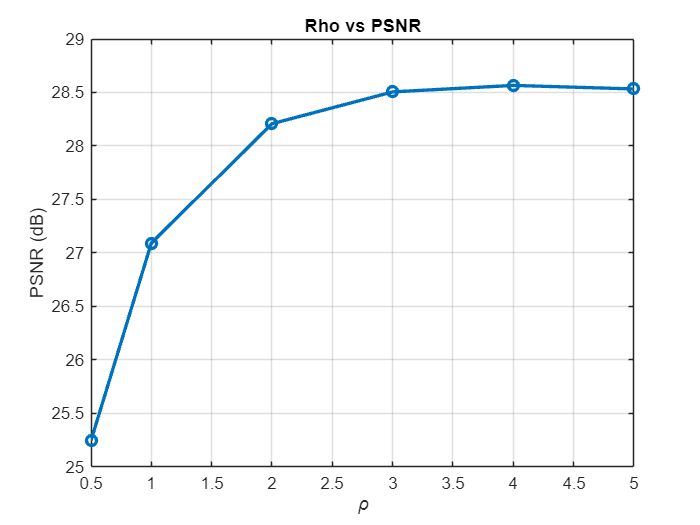


%% ===================================================
%% RHO EXPERIMENT
%% ===================================================

rho_vals = [0.5 1 2 3 4 5];
psnr_rho = zeros(length(rho_vals),1);

for i = 1:length(rho_vals)
psnr_rho(i) = run_ilstat(lambda_base,rho_vals(i),v_base,b_img,A,AT,img,innerIter,maxIter);
end

[~,idx] = max(psnr_rho);
best_rho = rho_vals(idx);

figure
plot(rho_vals,psnr_rho,'-o','LineWidth',2)
grid on
xlabel('\rho')
ylabel('PSNR (dB)')
title('Rho vs PSNR')

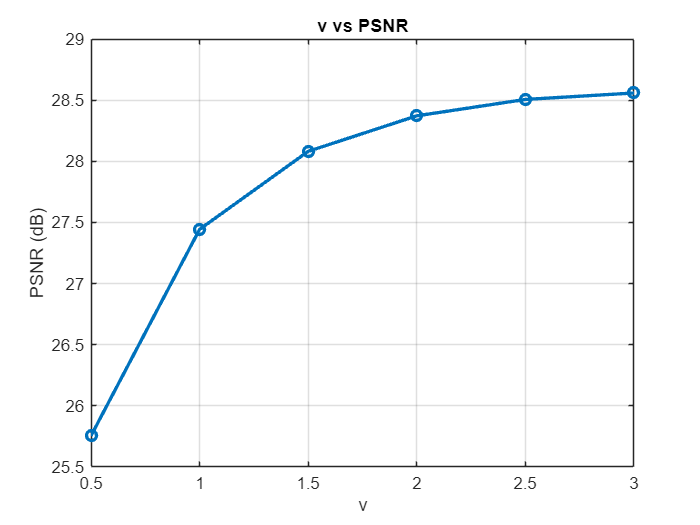


%% ===================================================
%% V EXPERIMENT
%% ===================================================

v_vals = [0.5 1 1.5 2 2.5 3];
psnr_v = zeros(length(v_vals),1);

for i = 1:length(v_vals)
psnr_v(i) = run_ilstat(lambda_base,rho_base,v_vals(i),b_img,A,AT,img,innerIter,maxIter);
end

[~,idx] = max(psnr_v);
best_v = v_vals(idx);

figure
plot(v_vals,psnr_v,'-o','LineWidth',2)
grid on
xlabel('v')
ylabel('PSNR (dB)')
title('v vs PSNR')


%% ================= PRINT BEST VALUES =================

fprintf('\nBest lambda = %.6f\n',best_lambda);


Best lambda = 0.000300


fprintf('Best rho = %.2f\n',best_rho);

Best rho = 4.00


fprintf('Best v = %.2f\n',best_v);

Best v = 3.00



%% ===================================================
%% FINAL RECONSTRUCTION
%% ===================================================

[x_rec,final_psnr,obj] = reconstruct(best_lambda,best_rho,best_v,b_img,A,AT,img,innerIter,maxIter);

fprintf('\nFinal PSNR = %.4f dB\n',final_psnr);


Final PSNR = 28.5257 dB



%% ================= SSIM =================

ssim_val = ssim(x_rec,img);
fprintf('SSIM = %.4f\n',ssim_val);

SSIM = 0.7797



%% ===================================================
%% WIENER FILTER COMPARISON
%% ===================================================

wiener_rec = deconvwnr(b_img,h,0.01);

mse_w = mean((img(:)-wiener_rec(:)).^2);
psnr_wiener = 10*log10(1/mse_w);

ssim_wiener = ssim(wiener_rec,img);

fprintf('\nWiener PSNR = %.4f dB\n',psnr_wiener);


Wiener PSNR = 27.3104 dB


fprintf('Wiener SSIM = %.4f\n',ssim_wiener);

Wiener SSIM = 0.8382


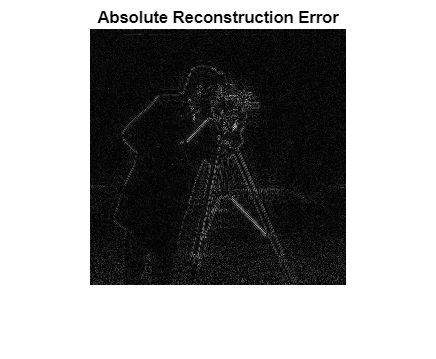


%% ===================================================
%% ERROR IMAGE
%% ===================================================

error_img = abs(img - x_rec);

figure
imshow(error_img,[])
title('Absolute Reconstruction Error')

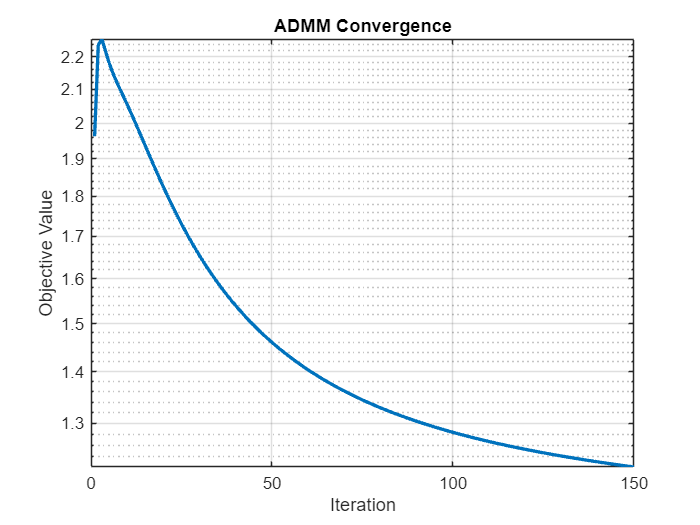


%% ===================================================
%% CONVERGENCE PLOT
%% ===================================================

figure
semilogy(obj,'LineWidth',2)
grid on
xlabel('Iteration')
ylabel('Objective Value')
title('ADMM Convergence')

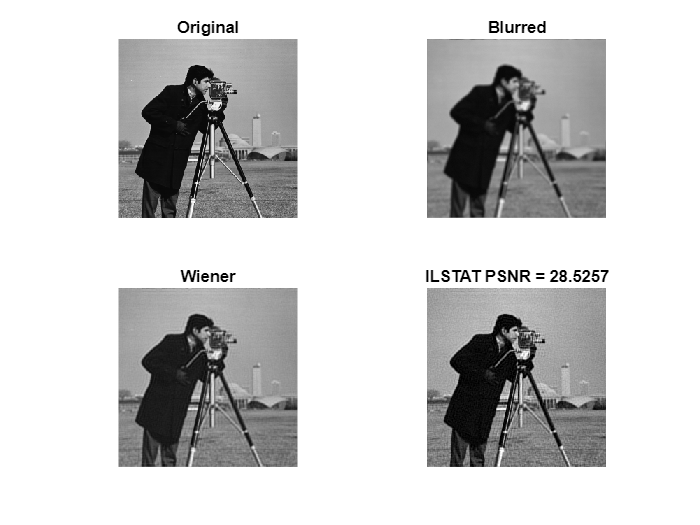


%% ===================================================
%% VISUAL COMPARISON
%% ===================================================

figure

subplot(2,2,1)
imshow(img)
title('Original')

subplot(2,2,2)
imshow(b_img)
title('Blurred')

subplot(2,2,3)
imshow(wiener_rec,[])
title('Wiener')

subplot(2,2,4)
imshow(x_rec,[])
title(['ILSTAT PSNR = ' num2str(final_psnr)])


runtime = toc;
fprintf('Runtime = %.2f seconds\n',runtime);

Runtime = 63.65 seconds



%% ===================================================
%% FUNCTION TO COMPUTE PSNR ONLY
%% ===================================================

function psnr_val = run_ilstat(lambda,rho,v,b_img,A,AT,img,innerIter,maxIter)

[x_rec,psnr_val,~] = reconstruct(lambda,rho,v,b_img,A,AT,img,innerIter,maxIter);

end

%% ===================================================
%% ILSTAT RECONSTRUCTION FUNCTION
%% ===================================================

function [x_rec,psnr_val,obj] = reconstruct(lambda,rho,v,b_img,A,AT,img,innerIter,maxIter)

[n1,n2] = size(img);
N = n1*n2;

b = b_img(:);

x = b;
y = b;
z = zeros(N,1);

obj = zeros(maxIter,1);

for k = 1:maxIter
    
x_old = x;

bk = y + z/rho;

for j = 1:innerIter
    
x_img = reshape(x,n1,n2);
Hx = A(x_img);

grad_img = AT(Hx - reshape(bk,n1,n2));
grad = grad_img(:);

x_temp = x - (1/v)*grad;

x = sign(x_temp).*max(abs(x_temp)-lambda,0);

end

Hx_vec = reshape(A(reshape(x,n1,n2)),[],1);

y = (b + rho*Hx_vec - z)/(1+rho);

z = z + rho*(y - Hx_vec);

obj(k) = norm(y-b)^2 + (rho/2)*norm(y-Hx_vec)^2;

if norm(x-x_old) < 1e-6
break
end

end

x_rec = reshape(x,n1,n2);
x_rec = min(max(x_rec,0),1);

mse = mean((img(:)-x_rec(:)).^2);
psnr_val = 10*log10(1/mse);

end